%solver for age and time model%
% uses analytical solution of pdes for constant source equation at each time step
clear
% global mu tau1 tau2 sigma beta n J BC alpha lam k r phi amp import

% Names of variables
% COMP = (1)  ;(ABSORB, DEFDOSE)
% COMP = (2)  ;(CENTRAL)
% COMP = (3)  ;(TRANSIT 1)
% COMP = (4)  ;(TRANSIT 2)
% COMP = (5)  ;(TRANSIT 3)
% COMP = (6)  ;(TRANSIT 4)
% COMP = (7)  ;(TRANSIT 5)
% COMP = (8)  ;(TRANSIT 6)
% COMP = (9)  ;(TRANSIT 7)


npeople = 1;
dosing = 40;
% flag = pregnant
% para is initial parasitaemia
% scale is the natural log of patient parasitaemia


%dimension of system
n=9;

%time steps
%size of time step
da=.003;
days=10;
%maximum age in hours for 10 days period
maxa=days*24;
%no. of timesteps
asteps=maxa/da;
nasteps=asteps;
%no. of timesteps in a day
oneday=24*(1/da);

% dosing times, 
% calculating index for mda
dt=da;
mda1=int32(24/dt);
mda2=int32(48/dt);
mda3=int32(72/dt);


%%PK piperaquine parameters
ACL = 0.75;
AV = 1;
M_WE = 48.5;

THETA=[78.0;129;0.982;1;0.58;-0.375;0.278];
% 1.CL/F L/h
% 2.V2/F  L
% 3. MT
% 4. F1
% 5. w
% 6. F1 Flag
% 7.F1 para

FLAG=1;

OMEGA=[1 ; 0.0162; 1; 0.088; 1; 0.23 ];
%CL
%V2
%MT
%F1
%W
%MTT_IOV

WT=48.5;
PARA=3.98;

TVCL = THETA(1)*(WT/M_WE)^ACL;
TVV2 = THETA(2)*(WT/M_WE)^AV;
TVMT = THETA(3);
TVF1 = THETA(4)*(1+THETA(6)*FLAG)*(1+THETA(7)*(PARA-3.98));


% initialize solution matrix - rows are people , columns are timesteps
vv=zeros(npeople,asteps+1);

tic
% run system for each person
for jj = 1: npeople
    
    % assign parameters to each person - mean estimate times randomly
    % distributed number with mean 0 and variance omega
    CL = TVCL;
    V2 = TVV2;
    MT = TVMT;
%     F10 = TVF1;  % CHECK THIS
    F10 = 1;
    F1 = F10;
    
    NN = 7;
    KTR = (NN+1)/MT;
    
    K13 = KTR;
    K34 = KTR;
    K45 = KTR;
    K56 = KTR;
    K67 = KTR;
    K78 = KTR;
    K89 = KTR;
    K92 = KTR;
    K20 = CL/V2;
    
    S2 = V2/1000;
    VD = V2;
    
    W=THETA(5);
    
    
    %set up V = solution matrix - rows is number of compartments or variable,
    %colums is number timesteps
    v=zeros(n,asteps+1);
    
    %initialize jacobian like matrix
    J=zeros(n,n);
    
    for m=2:asteps+1
        
        %  state transition matrix
        J=[
            -K13 0 0 0 0 0 0 0 0;
            0 -K20 0 0 0 0 0 0 K92;
            K13 0 -K34 0 0 0 0 0 0;
            0 0 K34 -K45 0 0 0 0 0;
            0 0 0 K45 -K56 0 0 0 0;
            0 0 0 0 K56 -K67 0 0 0;
            0 0 0 0 0 K67 -K78 0 0;
            0 0 0 0 0 0 K78 -K89 0;
            0 0 0 0 0 0 0 K89 -K92;
            ];
        
        % calc new V
        ej=expm(J(:,:)*dt);
        v(:,m)=ej*v(:,m-1);
        
        % assign different dosing absorption rates per dose.
        if (m==mda1)
            v(1,m)=dosing*F1+v(1,m);
        end
        
        if (m==mda2)
            v(1,m)=dosing*F1+v(1,m);
        end
        
        if (m==mda3)
            v(1,m)=dosing*F1+v(1,m);
        end
        
    end
    
    % keep solution for compartment 2 for each individual
    vv(jj,:)=v(2,:);
    
    xticktimes=(24:24:maxa);
    xticklabels=(1:10);
    v(2,end)=NaN;
%     patch((0:da:maxa),v(2,:),'black','EdgeColor','black','FaceAlpha',0.2);
%     set(gca,'FontSize',14,'XTick',xticktimes,'XTickLabel',1:1:days)
%     hold on
end

toc

Elapsed time is 5.992634 seconds.


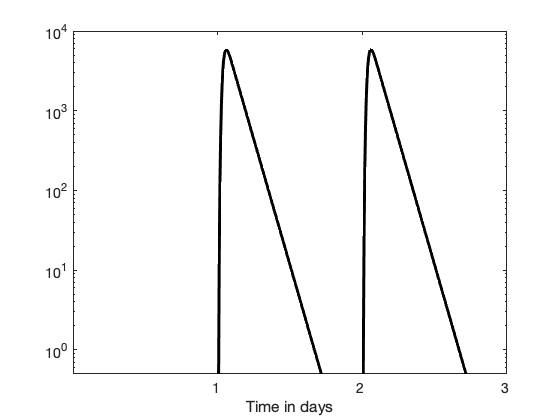


%millitres of blood in adult
bl=4.5*1000;
%nanograms in miligrams
ng=1*10^6;

mvv=vv(1,:);

figure(2)
semilogy((0:da:maxa),mvv*ng/bl,'k','LineWidth',3)
set(gca,'FontSize',14,'XTick',xticktimes,'XTickLabel',xticklabels)
ylim([0.5 10000])
xlim([0 72])
xlabel('Time in days')
hold on


% figure(3)
% semilogy((0:da:maxa),mvv,'k','LineWidth',3)
% set(gca,'FontSize',14,'XTick',xticktimes,'XTickLabel',xticklabels)
% ylim([0.5 100])
% xlim([0 48])
% xlabel('Time in days')

